Breakaway connector pin position calculator

Takes in the radius of the connector and the pin locations, and returns the x,y coordinates of each pin.

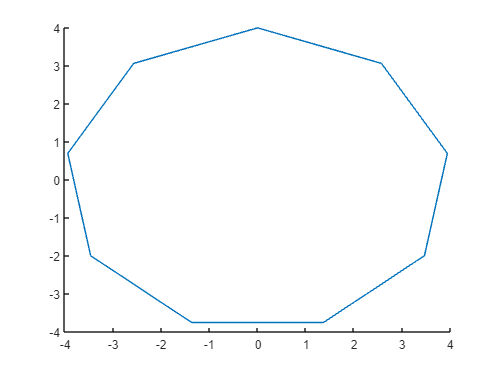

radius=4;%just an example
num_pins = 10;
theta=linspace(0,2*pi,10);%you can increase this if this isn't enough yet
x=radius*cos(theta);
y=radius*sin(theta);
theta=90;
rot = [];
R = [cosd(theta) -sind(theta); sind(theta) cosd(theta)];
for i = 1:size(x)
    rot = [rot R*[x;y]];
end
figure
hold on
plot(rot(1,:),rot(2,:))

disp('Coordinates:')

Coordinates:


disp(rot)

         0   -2.5712   -3.9392   -3.4641   -1.3681    1.3681    3.4641    3.9392    2.5712    0.0000
    4.0000    3.0642    0.6946   -2.0000   -3.7588   -3.7588   -2.0000    0.6946    3.0642    4.0000

